# Steps

%Load image 
% pre-processing
%segmentation
%Feature extraction
%Classification
%Bounding box annotaion
%Create text file
%Test and validate
%Documentaion
%Report
%Submission

## Specify input image

% Prompt user to specify input image file name
%image_file_name = input('Enter the name of the input image file (including extension): ', 's');

## Load Images and Specify users input

% Define path to the directory containing images
image_dir = 'C:\Users\649678\OneDrive - hull.ac.uk\University\3rd year\Machine vision and Sensor fusion\Matlab\ACW\601097_ACW1_images'

image_dir = 'C:\Users\649678\OneDrive - hull.ac.uk\University\3rd year\Machine vision and Sensor fusion\Matlab\ACW\601097_ACW1_images'


%List all files
image_files = dir(fullfile(image_dir, "*.jpg"));

% Check if any image is found
if isempty(image_files)
    disp('No image files found')
else
    % Display the list of image files found
    disp('List of image files:');
    for i = 1:numel(image_files)
        disp(image_files(i).name);
    end

    %Create an array to store all images
    all_images = cell(1, numel(image_files));

    % Prompt the user for an image file name
    file_index = input('Enter the index of the image file you want to process: ');

    % Validate the user input
    if file_index < 1 || file_index > numel(image_files)
        disp('Invalid input, Please enter a valid index.');
    else
        % Load the selected image
        selected_image_name = fullfile(image_dir, image_files(file_index).name);
        [~, image_name, ~] = fileparts(selected_image_name);
        disp(['Selected Image: ', image_name]);
        selected_image = imread(selected_image_name);
    end
end

List of image files:


P1020808.JPG
P1020809.JPG
P1020810.JPG
P1020813.JPG
P1020814.JPG
P1020819.JPG
P1020821.JPG
P1020822.JPG
P1020823.JPG
lego_01.jpg
lego_02.jpg
lego_03.jpg
lego_04.jpg
lego_05.jpg
lego_06.jpg
lego_07.jpg
lego_08.jpg
lego_09.jpg
lego_10.jpg
lego_11.jpg
lego_12.jpg
lego_13.jpg
lego_14.jpg
lego_15.jpg
lego_16.jpg
lego_17.jpg


Selected Image: P1020810


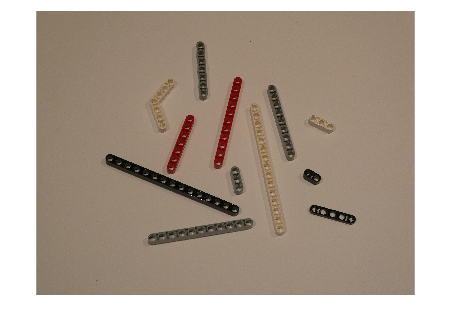

imshow(selected_image);

## Preprocessing and Feature Extraction

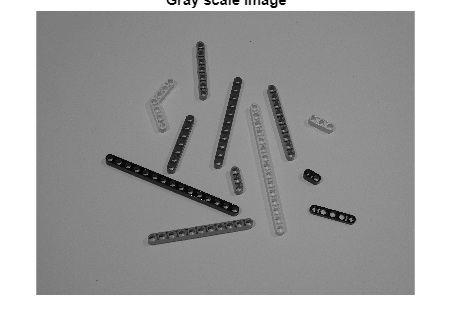

% Convert the RGB image to grayscale
grayImage = rgb2gray(selected_image);
imshow(grayImage);
title('Gray scale Image');

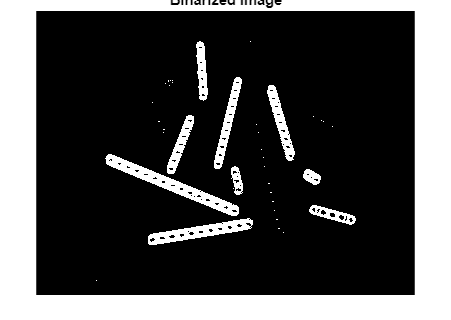


% Convert the grayscale image to a binary image using the threshold
binaryImage = imbinarize(grayImage, "global");

% Invert the binary mask if necessary
binaryImage = ~binaryImage;
imshow(binaryImage);
title('Binarized Image');

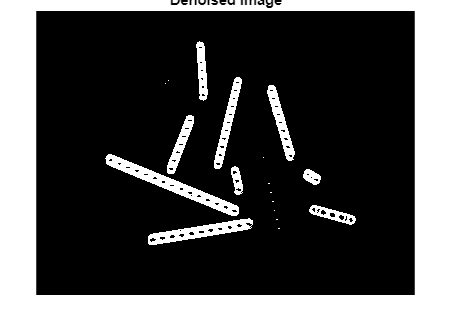


% Perform morphological opening to remove small objects (noise)
denoisedEdge = imopen(binaryImage , strel('disk', 3));

% Perform morphological closing to fill in small holes within objects
denoisedEdge = imclose(denoisedEdge, strel('disk', 3));

% Remove noise using median filtering
denoisedEdge = medfilt2(denoisedEdge, [1, 1]);
imshow(denoisedEdge);
title('Denoised Image');


% Label connected components in the binary mask
[labeledImage, numRegions] = bwlabel(denoisedEdge);
disp(numRegions);

    28




% Use regionprops to get shape features of the labeled regions
stats = regionprops(labeledImage, 'Area', 'BoundingBox', 'Centroid', 'Perimeter');

% Define a threshold for the minimum area of the bounding box
minAreaThreshold = 10000; % Adjust as needed

% Store centroids, bounding box coordinates, area, and perimeter of detected LEGO pieces
features = zeros(numRegions, 8); % Each row represents the features of one region

for i = 1:numRegions
    % Extract bounding box properties and area
    bbox = stats(i).BoundingBox;
    area = stats(i).Area;
    perimeter = stats(i).Perimeter;
    centroid = stats(i).Centroid;

    % Filter out small bounding boxes
    if area < minAreaThreshold
        continue;
    end
    
    % Store centroid, bounding box coordinates, area, and perimeter
    features(i, :) = [centroid, bbox, area, perimeter];
end

% Extract the widths and heights of the regions
widths = features(:, 5) - features(:, 3);  % Calculate width
heights = features(:, 6) - features(:, 4);  % Calculate height

% Transpose widths and heights for plotting
sizes = [widths, heights];  % Combine into one matrix

% Create a bar plot to display the sizes
figure;
% Debug bounding box coordinates
disp('Bounding Box Coordinates:');

Bounding Box Coordinates:


disp('Region | XMin | YMin | XMax | YMax');

Region | XMin | YMin | XMax | YMax


disp('----------------------------------');

----------------------------------


for i = 1:numRegions
    bbox = stats(i).BoundingBox;  % Retrieve bounding box for the current region
    xMin = round(bbox(1));
    yMin = round(bbox(2));
    xMax = round(bbox(1) + bbox(3));
    yMax = round(bbox(2) + bbox(4));
    fprintf('%6d | %5d | %5d | %5d | %5d\n', i, xMin, yMin, xMax, yMax);
    
    % Calculate width and height
    width = xMax - xMin;
    height = yMax - yMin;
    
    % Display width and height
    disp(['Region ' num2str(i) ' Dimensions: Width = ' num2str(width) ', Height = ' num2str(height)]);
end

     1 |   825 |  3690 |   838 |  3699


Region 1 Dimensions: Width = 13, Height = 9


     2 |   950 |  1959 |  2782 |  2814


Region 2 Dimensions: Width = 1832, Height = 855


     3 |  1531 |  2839 |  2974 |  3210


Region 3 Dimensions: Width = 1443, Height = 371


     4 |  1706 |  1504 |  1717 |  1514


Region 4 Dimensions: Width = 11, Height = 10


     5 |  1730 |  1492 |  1740 |  1504


Region 5 Dimensions: Width = 10, Height = 12


     6 |  1767 |   984 |  1784 |   999


Region 6 Dimensions: Width = 17, Height = 15


     7 |  1789 |  1422 |  2167 |  2236


Region 7 Dimensions: Width = 378, Height = 814


     8 |  1805 |   942 |  1821 |   959


Region 8 Dimensions: Width = 16, Height = 17


     9 |  2194 |   418 |  2351 |  1227


Region 9 Dimensions: Width = 157, Height = 809


    10 |  2430 |   903 |  2821 |  2167


Region 10 Dimensions: Width = 391, Height = 1264


    11 |  2664 |  2126 |  2839 |  2520


Region 11 Dimensions: Width = 175, Height = 394


    12 |  2711 |  2221 |  2716 |  2226


Region 12 Dimensions: Width = 5, Height = 5


    13 |  2755 |  2457 |  2760 |  2462


Region 13 Dimensions: Width = 5, Height = 5


    14 |  3107 |  2006 |  3124 |  2013


Region 14 Dimensions: Width = 17, Height = 7


    15 |  3132 |  2123 |  3148 |  2129


Region 15 Dimensions: Width = 16, Height = 6


    16 |  3162 |  1010 |  3545 |  2056


Region 16 Dimensions: Width = 383, Height = 1046


    17 |  3163 |  2241 |  3174 |  2246


Region 17 Dimensions: Width = 11, Height = 5


    18 |  3178 |  2359 |  3199 |  2368


Region 18 Dimensions: Width = 21, Height = 9


    19 |  3201 |  2480 |  3226 |  2491


Region 19 Dimensions: Width = 25, Height = 11


    20 |  3227 |  2602 |  3257 |  2612


Region 20 Dimensions: Width = 30, Height = 10


    21 |  3253 |  2725 |  3283 |  2736


Region 21 Dimensions: Width = 30, Height = 11


    22 |  3280 |  2848 |  3309 |  2859


Region 22 Dimensions: Width = 29, Height = 11


    23 |  3306 |  2973 |  3335 |  2986


Region 23 Dimensions: Width = 29, Height = 13


    24 |  3652 |  2164 |  3901 |  2384


Region 24 Dimensions: Width = 249, Height = 220


    25 |  3739 |  2653 |  4378 |  2927


Region 25 Dimensions: Width = 639, Height = 274


    26 |  3884 |  1534 |  3892 |  1539


Region 26 Dimensions: Width = 8, Height = 5


    27 |  3911 |  1497 |  3916 |  1502


Region 27 Dimensions: Width = 5, Height = 5


    28 |  3995 |  1587 |  4001 |  1592


Region 28 Dimensions: Width = 6, Height = 5


## Classification and Bounding box Annotations

% Define predefined LEGO sizes along with their part numbers
legoSizes = {
  [203, 208], '3002'; % dimensions for Brick 2x3
  [272, 272], '3002'; % dimensions for Brick 2x3
  [344, 363], '3002'; % dimensions for Brick 2x3
  [1360, 1362], '3649'; % dimensions for Technic gear 40 tooth
  [505, 487], '3649'; % dimensions for Technic gear 40 tooth
  [834, 849], '3648b'; % dimensions for Technic gear 24 tooth with single axle hole
  [372, 378], '3648b'; % dimensions for Technic gear 24 tooth with single axle hole
  [306, 307], '3648b'; % dimensions for Technic gear 24 tooth with single axle hole
  [334, 633], '32140'; % dimensions for Technic beam 2x4 liftarm bent 90
  [458, 633], '32140'; % dimensions for Technic beam 2x4 liftarm bent 90
  [551, 547], '32140'; % dimensions for Technic beam 2x4 liftarm bent 90
  [402, 218], '32140'; % dimensions for Technic beam 2x4 liftarm bent 90
  [666, 740], '32526'; % dimensions for Technic beam 3x5 bent 90
  [381, 969], '32348'; % dimensions for Technic beam 4x4 bent 
  [825, 1144], '6629'; % dimensions for Technic beam 4x6 bent 
  [869, 1487], '32009'; % dimensions for Technic beam 3x3.8x7 liftarm bent 45 double
  [890, 878], '32009'; % dimensions for Technic beam 3x3.8x7 liftarm bent 45 double
  [966, 878], '32009'; % dimensions for Technic beam 3x3.8x7 liftarm bent 45 double
  [808, 709], '32009'; % dimensions for Technic beam 3x3.8x7 liftarm bent 45 double
  [1075, 886], '32009'; % dimensions for Technic beam 3x3.8x7 liftarm bent 45 double
  [627, 835], '32009'; % dimensions for Technic beam 3x3.8x7 liftarm bent 45 double
  [176, 394], '32523'; % dimensions for Technic beam 3
  [140, 366], '32523'; % dimensions for Technic beam 3
  [281, 173], '32523'; % dimensions for Technic beam 3
  [461, 305], '32523'; % dimensions for Technic beam 3
  [155, 369], '32523'; % dimensions for Technic beam 3
  [117, 269], '32523'; % dimensions for Technic beam 3
  [482, 118], '32523'; % dimensions for Technic beam 3
  [172, 277], '32523'; % dimensions for Technic beam 3
  [117, 296], '32523'; % dimensions for Technic beam 3
  [588, 691], '32316'; % dimensions for Technic beam 5
  [383, 336], '32316'; % dimensions for Technic beam 5
  [366, 366], '32316'; % dimensions for Technic beam 5
  [300, 307], '3003'; % dimensions for Brick 2x2
  [336, 336], '3003'; % dimensions for Brick 2x2
  [226, 135], '3003'; % dimensions for Brick 2x2
  [236, 251], '3003'; % dimensions for Brick 2x2
  [349, 377], '3003'; % dimensions for Brick 2x2
  [350, 243], '3001'; % dimensions for Brick 2x4
  [390, 415], '3002'; % dimensions for Brick 2x3
  [281, 205], '3002'; % dimensions for Brick 2x3
  [198, 77], '3003'; % dimensions for Brick 2x2
  [253, 275], '3003'; % dimensions for Brick 2x2
  [253, 266], '3003'; % dimensions for Brick 2x2
  [1211, 1163], '3033'; % dimensions for Plate 6x10
  [1141, 1200], '3033'; % dimensions for Plate 6x10
  [594, 994], '3033'; % dimensions for Plate 6x10
  [227, 346], '3002'; % dimensions for Brick 2x3
  [264, 285], '3003'; % dimensions for Brick 2x2
  [228, 2319], '32278'; % dimensions for Technic beam 15
  [1832, 855], '32278'; % dimensions for Technic beam 15
  [1618, 902], '32278'; % dimensions for Technic beam 15
  [788, 1154], '32278'; % dimensions for Technic beam 15
  [1740, 733], '32525'; % dimensions for Technic beam 11
  [1550, 886], '32525'; % dimensions for Technic beam 11
  [391, 1264], '32525'; % dimensions for Technic beam 11
  [1443, 372], '32525'; % dimensions for Technic beam 11
  [464, 1182], '32525'; % dimensions for Technic beam 11
  [1341, 248], '32525'; % dimensions for Technic beam 11
  [249, 1070], '32525'; % dimensions for Technic beam 11
  [304, 1266], '32525'; % dimensions for Technic beam 11
  [587, 1215], '32525'; % dimensions for Technic beam 11
  [913, 1113], '32525'; % dimensions for Technic beam 11
  [439, 1258], '32525'; % dimensions for Technic beam 11
  [1380, 630], '32525'; % dimensions for Technic beam 11
  [812, 767], '32525'; % dimensions for Technic beam 11
  [758, 425], '11478'; % dimensions for Technic beam 5x0.5 liftarm with axle hoels at both ends
  [639, 274], '11478'; % dimensions for Technic beam 5x0.5 liftarm with axle hoels at both ends
  [580, 291], '11478'; % dimensions for Technic beam 5x0.5 liftarm with axle hoels at both ends
  [351, 527], '11478'; % dimensions for Technic beam 5x0.5 liftarm with axle hoels at both ends
  [303, 426], '11478'; % dimensions for Technic beam 5x0.5 liftarm with axle hoels at both ends
  [354, 511], '11478'; % dimensions for Technic beam 5x0.5 liftarm with axle hoels at both ends
  [764, 466], '11478'; % dimensions for Technic beam 5x0.5 liftarm with axle hoels at both ends
  [160, 457], '11478'; % dimensions for Technic beam 5x0.5 liftarm with axle hoels at both ends
  [660, 604], '99773'; % dimensions for Technic beam 5x3x0.5 liftarm triangle type 2
  [672, 603], '99773'; % dimensions for Technic beam 5x3x0.5 liftarm triangle type 2
  [1675, 2909], '39794'; % dimensions for Technic beam 11x7 with open centre 9x5
  [732, 999], '39794'; % dimensions for Technic beam 11x7 with open centre 9x5
  [1031, 1260], '39794'; % dimensions for Technic beam 11x7 with open centre 9x5
  [1327, 667], '39794'; % dimensions for Technic beam 11x7 with open centre 9x5
  [859, 1036], '39794'; % dimensions for Technic beam 11x7 with open centre 9x5
  [890, 948], '64178'; % dimensions for Technic beam 11x5 with open centre 5x3
  [721, 775], '64178'; % dimensions for Technic beam 11x5 with open centre 5x3
  [529, 682], '64178'; % dimensions for Technic beam 11x5 with open centre 5x3
 


  % Add more LEGO sizes and corresponding part numbers as needed
};

% Define tolerance levels for size variations
tol_width = 10; % Adjust tolerance for width as needed
tol_height = 10; % Adjust tolerance for height as needed

% Display the labeled image with bounding boxes, part numbers, and dimensions
figure;
imshow(selected_image);
hold on;

for i = 1:numRegions
    % Extract bounding box properties
    bbox = [features(i, 3), features(i, 4), features(i, 5), features(i, 6)];
   
    % Calculate bounding box coordinates
    xMin = round(bbox(1));
    yMin = round(bbox(2));
    width = round(bbox(3));
    height = round(bbox(4));
    xMax = xMin + width;
    yMax = yMin + height;
   
    % Define region dimensions
    regionDimensions = [width, height];
  
    % Display dimensions
    disp(['Region ' num2str(i) ' Dimensions: Width = ' num2str(width) ', Height = ' num2str(height)]);
   
    % Initialize part number
    partNumber = '';

    % Iterate through predefined LEGO sizes
    for j = 1:size(legoSizes, 1)
        pieceSize = legoSizes{j, 1}; % Extract predefined size
     
        % Check if dimensions match within tolerance
        if numel(regionDimensions) == numel(pieceSize)
            sizeDiff = abs(regionDimensions - pieceSize); % Compare width and height
       
            if all(sizeDiff <= [tol_width, tol_height])
                partNumber = legoSizes{j, 2}; % Assign part number
                break; % Exit loop once a match is found
            end
        else
            % Handle incompatible sizes (optional: display a warning)
            disp(['Warning: Incompatible sizes for piece ' legoSizes{j, 2}]);
        end
    end
  
    % Draw bounding box
    rectangle('Position', [xMin, yMin, width, height], 'EdgeColor', 'g', 'LineWidth', 2);
   
    % Label with part number and dimensions
    text(xMin, yMin - 5, partNumber, 'Color', 'r', 'FontSize', 10, 'FontWeight', 'bold');
end

Region 1 Dimensions: Width = 0, Height = 0
Region 2 Dimensions: Width = 1832, Height = 855
Region 3 Dimensions: Width = 1443, Height = 371
Region 4 Dimensions: Width = 0, Height = 0
Region 5 Dimensions: Width = 0, Height = 0
Region 6 Dimensions: Width = 0, Height = 0
Region 7 Dimensions: Width = 378, Height = 814
Region 8 Dimensions: Width = 0, Height = 0
Region 9 Dimensions: Width = 157, Height = 809
Region 10 Dimensions: Width = 391, Height = 1264
Region 11 Dimensions: Width = 175, Height = 394
Region 12 Dimensions: Width = 0, Height = 0
Region 13 Dimensions: Width = 0, Height = 0
Region 14 Dimensions: Width = 0, Height = 0
Region 15 Dimensions: Width = 0, Height = 0
Region 16 Dimensions: Width = 383, Height = 1046
Region 17 Dimensions: Width = 0, Height = 0
Region 18 Dimensions: Width = 0, Height = 0
Region 19 Dimensions: Width = 0, Height = 0
Region 20 Dimensions: Width = 0, Height = 0
Region 21 Dimensions: Width = 0, Height = 0
Region 22 Dimensions: Width = 0, Height = 0
Region 23

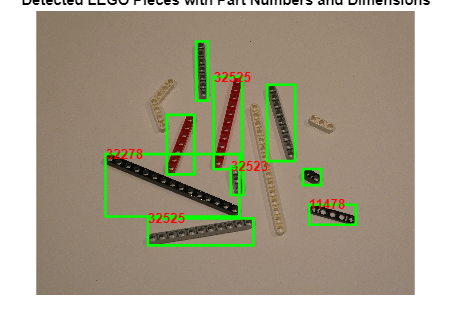


title('Detected LEGO Pieces with Part Numbers and Dimensions');
hold off;

## Output Image and Text File

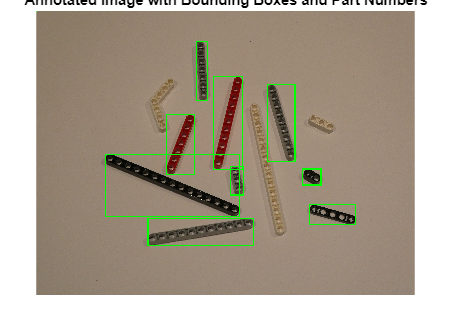

% Define output directory for images and text files
output_dir = 'C:\Users\649678\OneDrive - hull.ac.uk\University\3rd year\Machine vision and Sensor fusion\Matlab\ACW\Output_images';

% Define output image file name
output_image_name = fullfile(output_dir, [image_name '_labelled.jpg']);

% Create a copy of the original image for annotation
annotated_image = selected_image;

% Open text file for writing detection details
output_text_file = fopen(fullfile(output_dir, [image_name '_detections.txt']), 'w');


if output_text_file ~= -1  % Check if file opened successfully
    % Write header to text file (after successful opening)
    fprintf(output_text_file, 'ID,xc,yc,x1,y1,x2,y2\n');
    
    % Loop through detected regions and write details to text file, and draw bounding boxes
    for i = 1:numRegions
        % Extract bounding box properties
        bbox = [features(i, 3), features(i, 4), features(i, 5), features(i, 6)];
        centroid = features(i, 1:2);
        
        % Initialize part number
        partNumber = '';
    
        % Iterate through predefined LEGO sizes
        for j = 1:size(legoSizes, 1)
            pieceSize = legoSizes{j, 1}; % Extract predefined size
         
            % Check if dimensions match within tolerance
            if numel(regionDimensions) == numel(pieceSize)
                sizeDiff = abs(regionDimensions - pieceSize); % Compare width and height
           
                if all(sizeDiff <= [tol_width, tol_height])
                    partNumber = legoSizes{j, 2}; % Assign part number
                    break; % Exit loop once a match is found
                end
            else
                % Handle incompatible sizes (optional: display a warning)
                disp(['Warning: Incompatible sizes for piece ' legoSizes{j, 2}]);
            end
        end
        
        % Draw bounding box on annotated image (use existing partNumber)
        annotated_image = insertShape(annotated_image, 'Rectangle', bbox, 'Color', 'g', 'LineWidth', 15);
    
        % Label with part number (use existing partNumber)
        annotated_image = insertText(annotated_image, [xMin, yMin - 5], partNumber, 'FontSize', 20, 'TextColor', 'red', 'BoxOpacity', 0.8, 'TextColor', 'black');
    
        % Write detection details to text file
        fprintf(output_text_file, '%s,%d,%d,%d,%d,%d,%d\n', partNumber, round(centroid(1)), round(centroid(2)), xMin, yMin, xMax, yMax);
    end
    
    % Close text file
    fclose(output_text_file);

else
    disp('Error opening output text file!');  % Handle error (optional)
end

% Display the annotated image for debugging
figure;
imshow(annotated_image);
title('Annotated Image with Bounding Boxes and Part Numbers');


% Write annotated image to file
imwrite(annotated_image, output_image_name);

disp(['Output image saved as ' output_image_name]);

Output image saved as C:\Users\649678\OneDrive - hull.ac.uk\University\3rd year\Machine vision and Sensor fusion\Matlab\ACW\Output_images\P1020810_labelled.jpg


disp(['Detection details saved as ' fullfile(output_dir, [image_name '_detections.txt'])]);

Detection details saved as C:\Users\649678\OneDrive - hull.ac.uk\University\3rd year\Machine vision and Sensor fusion\Matlab\ACW\Output_images\P1020810_detections.txt
